# CN - L5 -  Exercici 1

Activitat d'evaluació continuada 

## Estudi ZAF

 Les dades de la taula següent estan relacionades amb l'esperança de vida al nèixer dels ciutadants dels *Estats Units*  


$$\scriptstyle\begin{array}{|c|cccccc|} \hline any & 1960& 1965 & 1970 & 1975 &1980 & 1985 & 1990 &1995 & 2000& 2005 & 2010 & 2015\\ \hline ZAF &52.2 & 53.9 & 55.9& 57.2 & 57.8 & 59.8 & 62.1 & 61.3& 56.4 & 52.6 & 55.9 & 61.9\\ \hline \end{array} $$


**Numèricament és millor que considereu la taula inicial amb abscisses **$\( 0,1,\dots,12 \)$**  o que centreu les dades o que les estandaritzeu.  Altrement els resultats no són correctes!!**

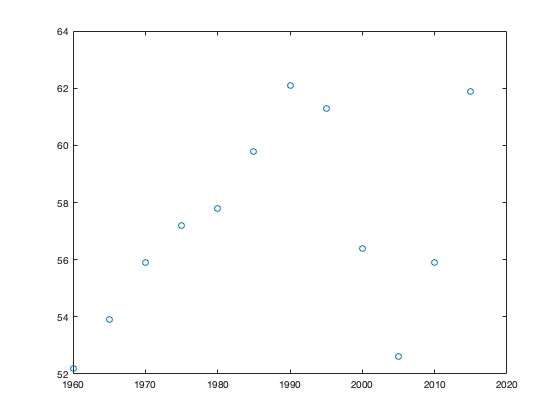

format shortG
x=1960:5:2015;
y=[52.2 53.9 55.9 57.2 57.8 59.8 62.1 61.3 56.4 52.6 55.9 61.9];
y_escalat=1e6*y;
plot(x,y,'o')

**a)**** Useu el ****polinomi interpolador de grau 11**** (escalat) per estimar l'esperança de vida dels anys **$ \( 1963,\ 1998\ i\ 2011\)$**. Compareu els valors obtinguts, amb les xifres oficials. **

year=[1963, 1998, 2011];
calculated_age1 = polyinterp(x,y_escalat,year)./1e6;
oficial = [53.5, 58.6, 58.9];
disp(array2table([year',calculated_age1',oficial'], 'VariableNames',{'any','edad calculada','oficial'}))

    any     edad calculada    oficial
    ____    ______________    _______

    1963        53.939         53.5  
    1998         58.66         58.6  
    2011        57.125         58.9  



**b)** **Useu un ****spline natural**** per estimar l'esperança de vida dels anys  **$1963,\ 1998\ i\  2011$**. Compareu els valors obtinguts, amb les xifres oficials.**

calculated_age2 = interp1(x,y_escalat,year,'spline')./1e6;
disp(array2table([year',calculated_age2',oficial'], 'VariableNames',{'any','edad calculada','oficial'}))

    any     edad calculada    oficial
    ____    ______________    _______

    1963        53.124         53.5  
    1998        58.628         58.6  
    2011        57.112         58.9  



**c)** **Determineu un ****polinomi  per minims quadrats**** de grau més petit que 5. Consulteu l'article **[**Finding the optimum polynomial order to use for regression**](https://autarkaw.org/2008/07/05/finding-the-optimum-polynomial-order-to-use-for-regression/)**.   Per cada polinomi, calculeu el residu i el paramètre definit en l'article referenciat; raoneu els resultats obtinguts i argumenteu l'elecció del polinomi. Finalment, escollit el polinomi, compareu els valors obtinguts, amb les xifres oficials per cada pais.**

[r1,S1,mu1]=polyfit(x,y_escalat,1); 
[r2,S2,mu2]=polyfit(x,y_escalat,2);
[r3,S3,mu3]=polyfit(x,y_escalat,3); 
[r4,S4,mu4]=polyfit(x,y_escalat,4); 
residu = [S1.normr/1e6,S2.normr/1e6,S3.normr/1e6,S4.normr/1e6].^2;
grau = [1:4];
parametre = residu./(11-grau);


`residus per als polinomis del mètode dels mínims quadrats`

disp(array2table([grau',residu',parametre'], 'VariableNames',{'grau','residu^2','parametre'}))

    grau    residu^2    parametre
    ____    ________    _________

     1       109.76      10.976  
     2       87.026      9.6695  
     3       67.035      8.3793  
     4       24.182      3.4546  



`Polinomi candidat amb paràmetre mínim (escalat), grau =  4`

calculated_age3 = (polyval(r4,year,[],mu4))/1e6;
disp(array2table([year',calculated_age3',oficial'], 'VariableNames',{'any','edad calculada','oficial'}))

    any     edad calculada    oficial
    ____    ______________    _______

    1963        52.393         53.5  
    1998        57.377         58.6  
    2011        56.413         58.9  



**d) ****Extrapoleu**** un valor per l'any **$\(2018\)$** pels tres models obtinguts.  Observant les dades  oficials,  els resultats obtinguts pels models estudiats són vàlids per estimar amb precisió l'esperança de vida per l'any **$\(2018\)$**?**

Observant els resultats obtinguts podem concloure que els resultats pels models estudiats **no** són vàlids per estimar amb precisió l'esperança de vida per l'any 2018 ja que ni tan sols s'apropen el resultat oficial. Això es degut a que l'extrapolació és subjecte a una major incertesa i a un major risc de produir resultats sense sentit. 

disp(array2table([63.9; polyinterp(x,y,2018); interp1(x,y,2018,'spline'); (polyval(r4,2018,[],mu4))/1e6],'VariableNames',{'2018'},"RowNames",{'ZAF_Official','ZAF_M1','ZAF_M2','ZAF_M3'}))

                     2018 
                    ______

    ZAF_Official      63.9
    ZAF_M1          76.133
    ZAF_M2          63.826
    ZAF_M3          68.335



**e)** **Feu ****una gràfica**** on apareguin les dades (representades per una rodona) i les tres solucions trobades. Quina seria la millor corba  per representar les dades donades. Argumenta i raona la teva resposta.**

Com podem obervar a la gràfica, la corba que s'aproxima més a les dades és l'obtinguda pel mètode de l'spline natural i per tant, es la  corba més adequada per representar-les.

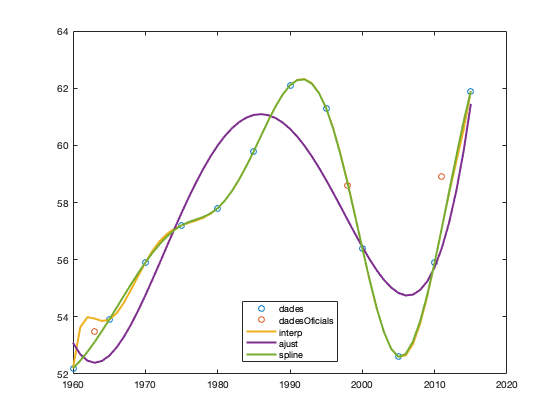

z=1960:1:2015;
plot(x,y,'o')
hold on
plot(year,oficial,'o')
plot(z,polyinterp(x,y_escalat,z)./1e6,'LineWidth',2)
plot(z,(polyval(r4,z,[],mu4))/1e6,'LineWidth',2)
plot(z,interp1(x,y_escalat,z,'spline')./1e6,'LineWidth',2)
legend('dades','dadesOficials','interp','ajust','spline','Location',"best")
hold off

`Funció auxiliar `

function v = polyinterp(x,y,u)
%POLYINTERP  Polynomial interpolation.
%   v = POLYINTERP(x,y,u) computes v(j) = P(u(j)) where P is the
%   polynomial of degree d = length(x)-1 with P(x(i)) = y(i).

%   Copyright 2014 Cleve Moler
%   Copyright 2014 The MathWorks, Inc.

% Use Lagrangian representation.
% Evaluate at all elements of u simultaneously.

n = length(x);
v = zeros(size(u));
for k = 1:n
   w = ones(size(u));
   for j = [1:k-1 k+1:n]
      w = (u-x(j))./(x(k)-x(j)).*w;
   end
   v = v + w*y(k);
end
end